## Edge detection using wavelet transformation  

### Sources

[https://www2.humusoft.cz/www/papers/tcb10/078_petrova.pdf](https://www2.humusoft.cz/www/papers/tcb10/078_petrova.pdf)

https://www.mdpi.com/2076-3417/13/3/1837

### Single level wavelet

#### Edge detection

% Step 1: Read the image
img_path  ='img/cameraman.tif';
img_path  ='img/portrait_2.png';

original_image = imread(img_path);

% Step 2: Convert the image to grayscale (if it's a color image)
if size(original_image, 3) == 3
    gray_image = rgb2gray(original_image);
else
    gray_image = original_image;
end

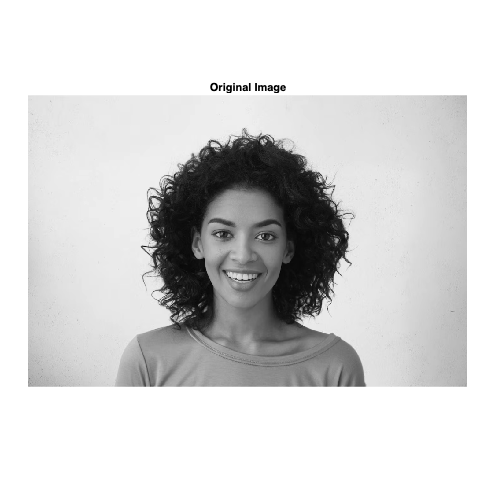

% Step 2: Perform a wavelet transform (e.g., using Haar wavelet)
wname = 'haar';
[cA, cH, cV, cD] = dwt2(gray_image, wname);

% Step 3: Replace approximation coefficients (LL) with zeros
cA = zeros(size(cA)); % Set all approximation coefficients to zeros
%cA = edge(cA, 'canny'); % Set all approximation coefficients to zeros

% Step 4: Reconstruct the modified image
rec_cA = idwt2(cA, cH, cV, cD, 'haar');

% Step 6: Display the results
my_fig = figure;
imshow(gray_image); title('Original Image'); set(my_fig, 'Position', [0 0 1000 1000])

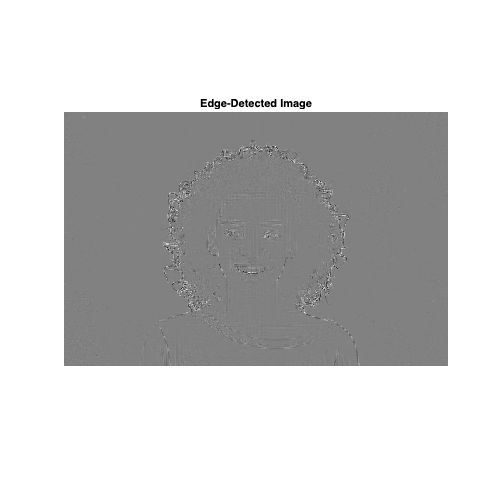

my_fig = figure;
imshow(rec_cA, [], 'InitialMagnification', 'fit'); title('Edge-Detected Image'); set(my_fig, 'Position', [0 0 1000 1000])

### Multiple level wavelet

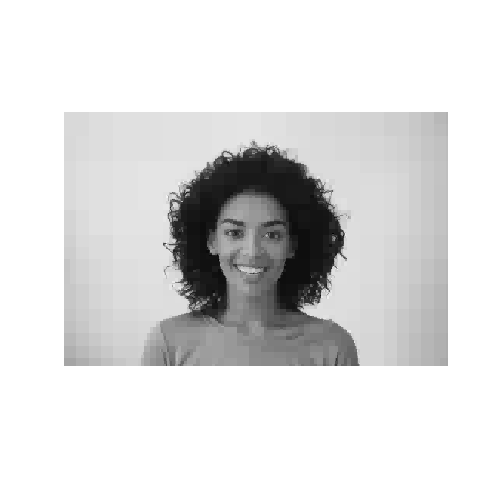

N = 8; % Set the number of levels
wname = 'haar';
[C,S] = wavedec2(gray_image, N, wname);

% Set the threshold value (adjust as needed)
threshold = 100;
C(abs(C) <= threshold) = 0;

cA = appcoef2(C,S, wname, N);
[cH ,cV, cD] = detcoef2('all', C, S, N);

enhanced_image = waverec2(C, S, wname);

my_fig = figure; imshow(enhanced_image, [], 'InitialMagnification', 'fit'); set(my_fig, 'Position', [0 0 1000 1000])

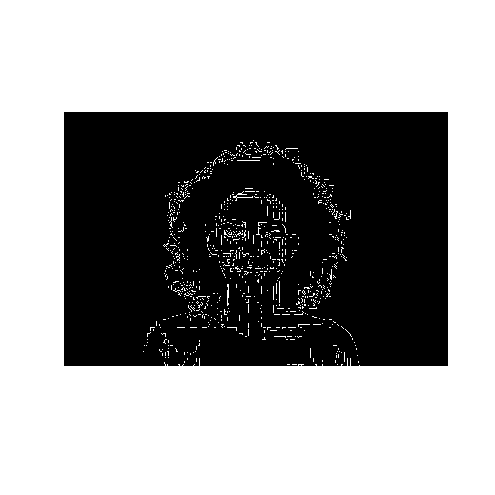

edgeImage = edge(enhanced_image,'Canny', 0.1);
my_fig = figure; imshow(edgeImage, [], 'InitialMagnification', 'fit'); set(my_fig, 'Position', [0 0 1000 1000])

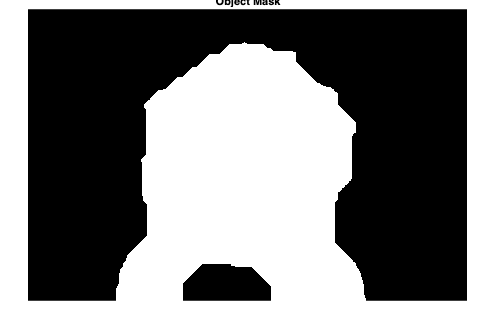

clf
% Define a structuring element (disk) for morphological operations
se = strel('disk', 75); % Adjust the size as needed

% Perform morphological dilation to connect edges
% Dilation is an operation that expands or thickens regions in a binary image.
% In this context, it is used to connect nearby edges or gaps in the edgeImage, which can help merge fragmented objects or regions.
dilatedImage = imdilate(edgeImage, se);

% Perform morphological erosion to refine the object mask
% rosion is an operation that shrinks or erodes regions in a binary image.
% In this context, it is used to refine the object mask by removing any noise 
% or small disconnected regions that may have been introduced during dilation.
objectMask = imerode(dilatedImage, se);

% Invert the object mask to obtain the background mask
backgroundMask = ~objectMask;

% Display the object mask and background mask
imshow(objectMask);
title('Object Mask');